# Parse .hmod Files

Suppose you have hank2_ssj.hmod in the working directory. Call in MATLAB

clear_hans
hans hank2_ssj

Parsing...ok!
Compiling dpopt_vfi
Building with 'MinGW64 Compiler (C++)'.
MEX completed successfully.


ans = struct with fields:
               parameters: {'beta'  'sigma'  'varphi'  'nu'  'chi0'  'chi1'  'omega'  'ra'  'r'  'w'  'tau'  'N'}
                var_shock: 'e'
                var_state: {'b'  'a'}
              var_pre_vfi: 'coh'
               var_policy: {'bp'  'ap'  'c'}
                  var_aux: {'chi'  'uce'}
                  var_agg: {'r'  'pii'  'Y'  'K'  'N'  'w'  'p'  'd'  'Bh'}
            var_agg_shock: 'm_shock'
           var_agg_params: {'G'  'Y_star'  'muw'  'kappap'  'kappaw'  'phi_y'  'beta'  'delta'  'omega'  'alpha'  'Bg'  'rstar'  'mup'  'phi'  'varphi'  'nu'  'epsI'  'Z'}
           var_agg_assign: {'ii'  'pshare'  'ra'  'I'  'psip'  'Q'  'tau'}
    var_agg_in_ind_params: {'r'  'N'  'w'  'ra'  'tau'}
            var_ind_in_eq: {'c'  'chi'  'uce'  'ap'  'bp'}


As shown, HANS parases the hmod file, compiles the mex files, and returns a structure that describes the model.

clear_hans in the first line clears any cached files generated before.

# Calibration and The Stationary Equilibrium

Call the generated code "solve_cali.m" to calibrate model parameters to satisfy data targets in stationary equilibria. By construction, the result of the calibration also returns the corresponding stationary equilibrium at the calibrated parameters.

tic;
cali_rslt = solve_cali;

Evaluating at var_agg: 0.976, 6.416, 
VFI converged (metric_v) 5.93717e-08, (metric_pol) 0 in 745 iterations
Range of b: 0, 21.3544
Range of a: 0, 76.6147
Equilbirium residual: -2.11182, -0.137683, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   4.478758e+00   2.116308e+00
Evaluating at var_agg: 0.9761, 6.416, 
VFI converged (metric_v) 1.76167e-08, (metric_pol) 0 in 566 iterations
Range of b: 0, 21.3544
Range of a: 0, 76.6147
Equilbirium residual: -1.99684, -0.128231, 
Evaluating at var_agg: 0.976, 6.41664, 
VFI converged (metric_v) 2.4074e-08, (metric_pol) 0 in 551 iterations
Range of b: 0, 21.3544
Range of a: 0, 76.6147
Equilbirium residual: -2.11176, -0.137825, 
Evaluating at var_agg: 0.977823, 6.57271, 
VFI converged (metric_v) 5.67098e-08, (metric_pol) 0 in 686 iterations
Range of b: 0, 21.3544
Range of a: 0, 91.6827
Equilbirium residual: 0.352755, 0.0130091, 


fprintf('Time used for Calibration:\n');

Time used for Calibration:


toc;

Elapsed time is 151.809596 seconds.


We can inspect the values of cali_rslt

cali_rslt

cali_rslt = struct with fields:
                vfi_rslt: [1×1 struct]
                   stats: [1×1 struct]
                 var_agg: [1×1 struct]
                    dist: [3×50×70 double]
              parameters: [1×1 struct]
          var_agg_params: [1×1 struct]
             shock_trans: [3×3 double]
    shock_invariant_dist: [3×1 double]
                   resid: [2×1 double]
               exit_flag: 1
               rslt_type: 'ss'
           solver_output: [1×1 struct]
           ind_rslt_dict: [1×1 ArrayKeyMap]


With all parameters and the corresponding stationary equilibrium calculated, we can directly proceed to the transition path computation. Nevertheless, as an extra check we can resolve the stationary equilibrium by passing the returned structure "cali_rslt" to "solve_ss.m" function:

tic;
ss_rslt = solve_ss(cali_rslt);

Evaluating at var_agg: 0.0125, 1, 
VFI converged (metric_v) 0.00771125, (metric_pol) 0 in 33 iterations
Range of b: 0, 21.3544
Range of a: 0, 83.8117
Equilbirium residual: -7.92235e-06, 1.57066e-10, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   6.276356e-11   7.922346e-06
Evaluating at var_agg: 0.0125, 1, 
VFI result reused
Range of b: 0, 21.3544
Range of a: 0, 83.8117
Equilbirium residual: -7.92235e-06, 1.57066e-10, 


fprintf('Time used for solving stationary equilibrium:\n');

Time used for solving stationary equilibrium:


toc;

Elapsed time is 0.435768 seconds.


As expected, the initial condition has already satisfied all conditions for the stationary equilibrium. As a result, the computaton stops right after the initial iteration.

All stationary equilibrium information is returned in the structure ss_rslt.

ss_rslt

ss_rslt = struct with fields:
                vfi_rslt: [1×1 struct]
                   stats: [1×1 struct]
                 var_agg: [1×1 struct]
                    dist: [3×50×70 double]
              parameters: [1×1 struct]
          var_agg_params: [1×1 struct]
             shock_trans: [3×3 double]
    shock_invariant_dist: [3×1 double]
                   resid: [2×1 double]
               exit_flag: 1
               rslt_type: 'ss'
           solver_output: [1×1 struct]
           ind_rslt_dict: [1×1 ArrayKeyMap]


We can inspect the values of equilibrium variables and verify that all calibration targets are satisfied:

ss_rslt.var_agg

ans = struct with fields:
          r: 0.0125
          Y: 1
    m_shock: 0
         ra: 0.0125
         mc: 0.9850
          K: 10
          N: 1
          w: 0.6600
          d: 0.1400
          p: 11.2000
        tau: 0.3561
      rstar: 0.0125
     Y_star: 1
        pii: 0
         Bh: 1.0400


To visualize the results, let's plot the policy functions for a given idiosyncratic shock in a 3-Dimensional graph:

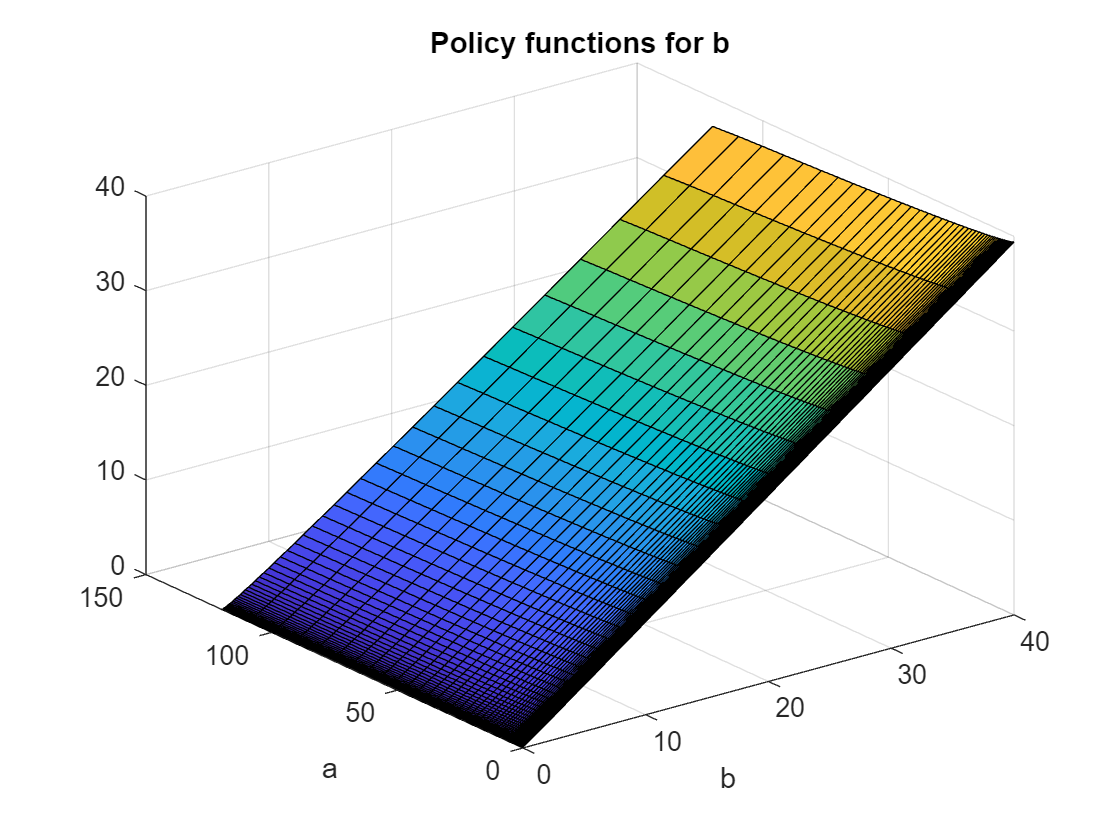

% Pick an idiosyncratic shock and the corresponding (b,a) mesh in 2-D
shock_idx = 2;
b_mesh_2d = squeeze(ss_rslt.vfi_rslt.var_state_mesh.b_mesh(shock_idx,:,:));
a_mesh_2d = squeeze(ss_rslt.vfi_rslt.var_state_mesh.a_mesh(shock_idx,:,:));

% Plot the VFI Policy in 3-D Mesh
surf(b_mesh_2d,a_mesh_2d,squeeze(ss_rslt.vfi_rslt.var_policy.bp(shock_idx,:,:)))
xlabel('b');
ylabel('a');
title('Policy functions for b');

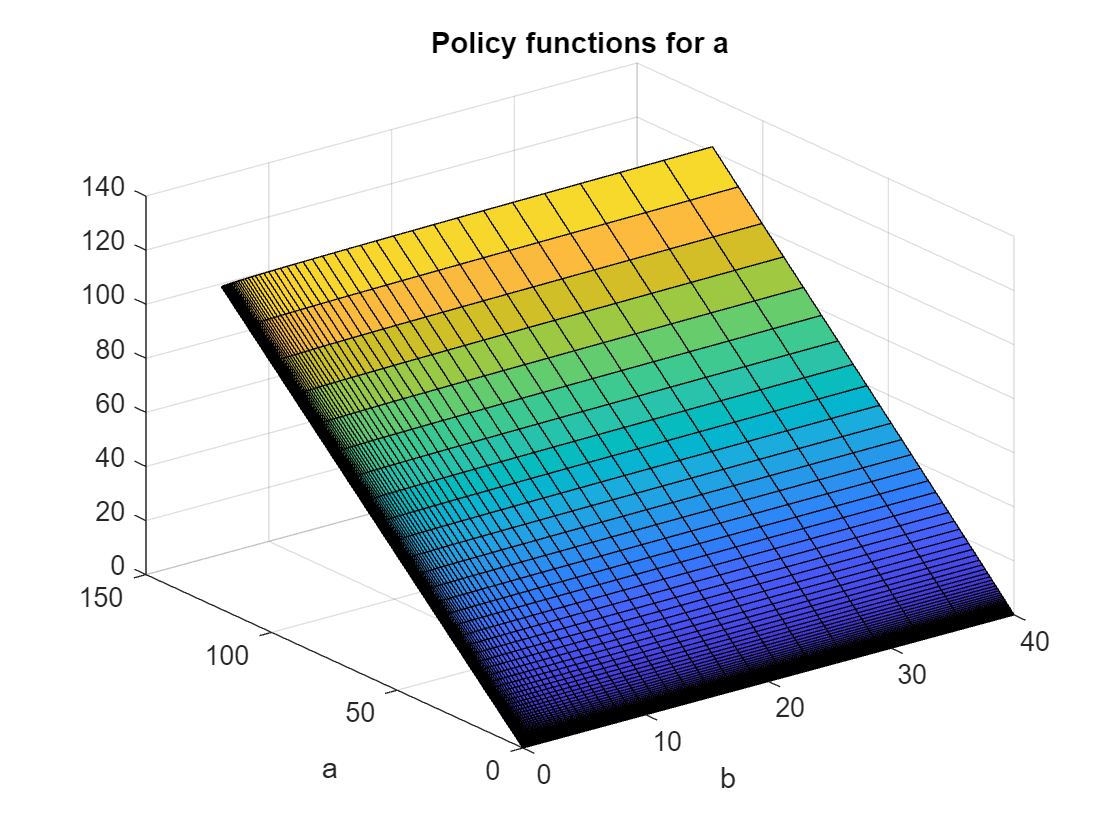


surf(b_mesh_2d,a_mesh_2d,squeeze(ss_rslt.vfi_rslt.var_policy.ap(shock_idx,:,:)))
xlabel('b');
ylabel('a');
title('Policy functions for a');

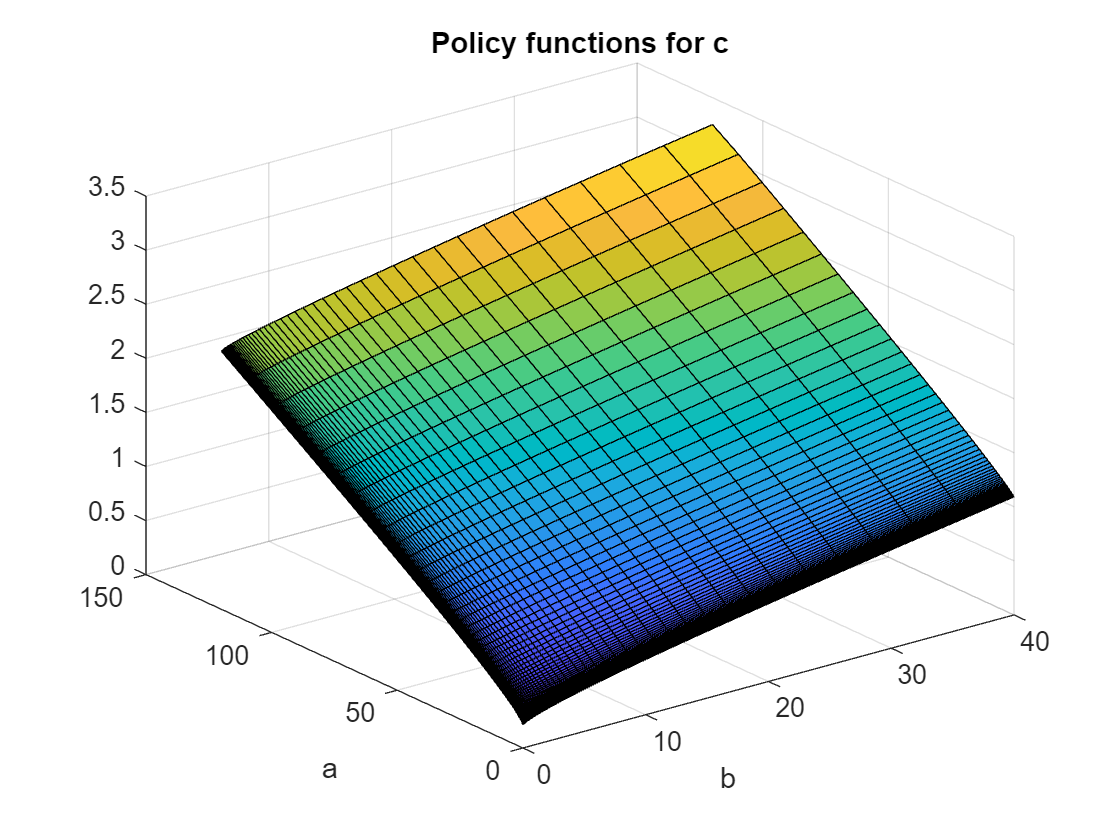


surf(b_mesh_2d,a_mesh_2d,squeeze(ss_rslt.vfi_rslt.var_policy.c(shock_idx,:,:)));
xlabel('b');
ylabel('a');
title('Policy functions for c');

We can also plot the joint stationary distribution over (b, a), as well as the marginal distribution over b or a.

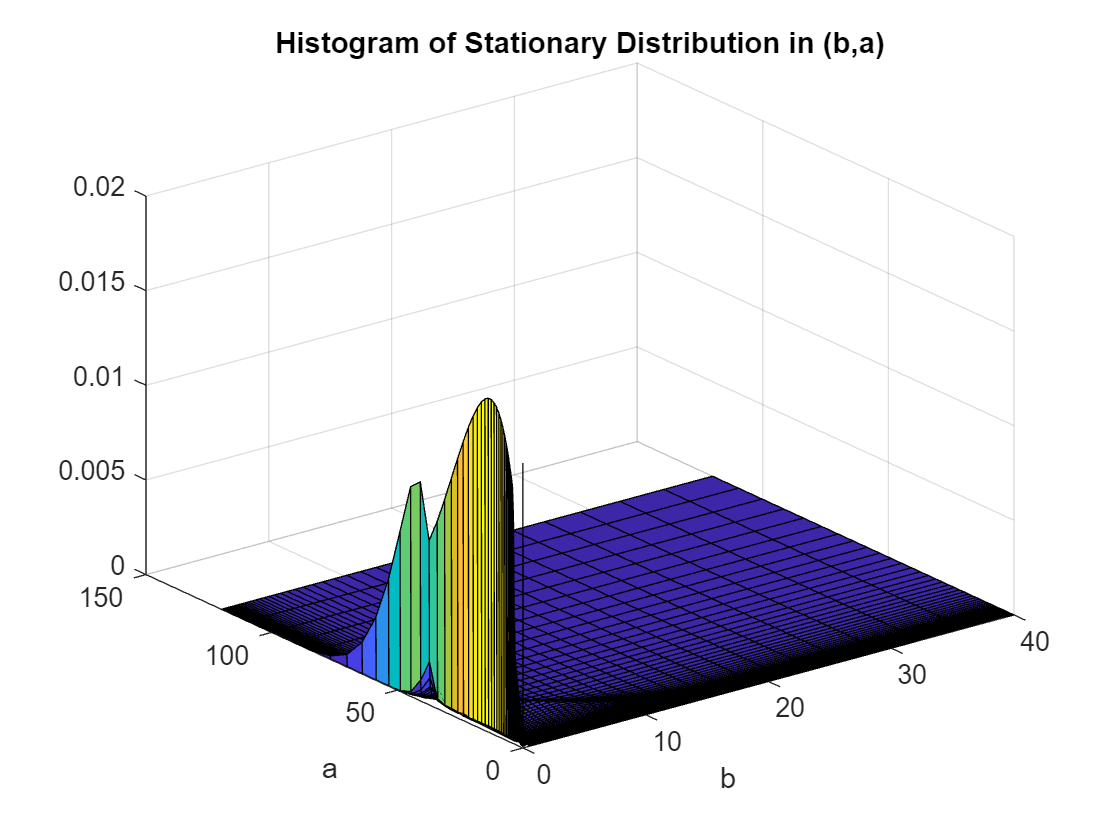

% Extract (b,a) mesh in 2-D
b_mesh_2d = squeeze(ss_rslt.vfi_rslt.var_state_mesh.b_mesh(1,:,:));
a_mesh_2d = squeeze(ss_rslt.vfi_rslt.var_state_mesh.a_mesh(1,:,:));

bgrid = ss_rslt.vfi_rslt.var_state.b(:); % b grid
agrid = ss_rslt.vfi_rslt.var_state.a(:); % a grid

% Plot the histogram of the Stationary Distribution in 3-D Mesh
dist_2d = squeeze(sum(ss_rslt.dist)); % histogram on (b,a) grid
dist_b = sum(dist_2d,2); % histogram on b grid
dist_a = reshape(sum(dist_2d,1),[],1); % histogram on a grid

surf(b_mesh_2d,a_mesh_2d,dist_2d); 
xlabel('b');
ylabel('a');
title('Histogram of Stationary Distribution in (b,a)');

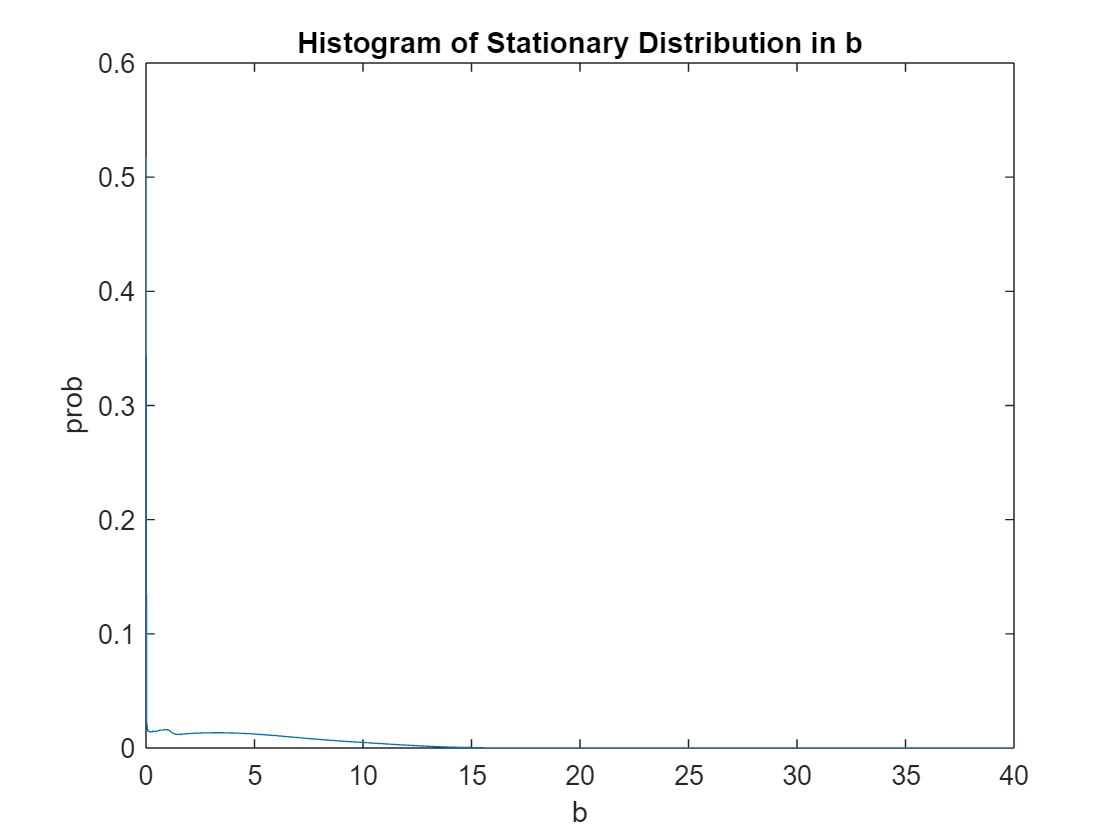

plot(bgrid,dist_b); 
xlabel('b');
ylabel('prob');
title('Histogram of Stationary Distribution in b');

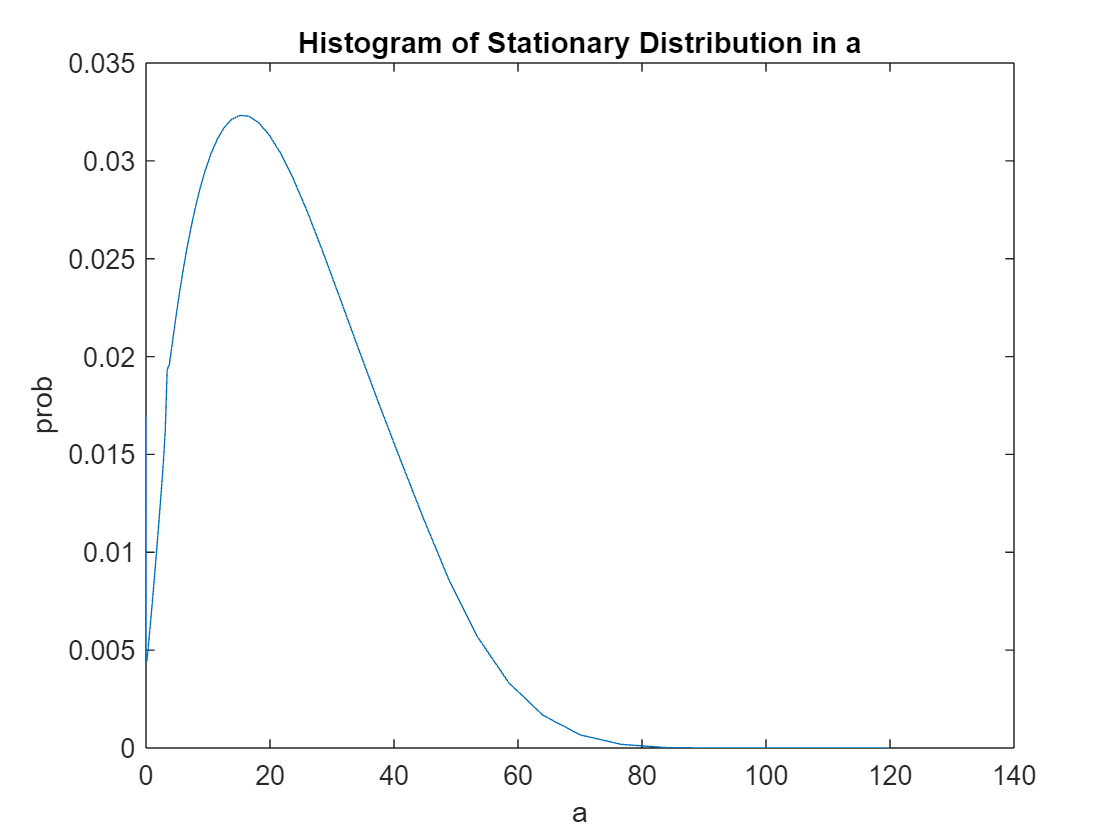

plot(agrid,dist_a); 
xlabel('a');
ylabel('prob');
title('Histogram of Stationary Distribution in a');

# Solve the Transition Path After A Temporay Shock

## Solve the linearized transition path

We first construct the sequence of monetary policy shocks to the Taylor rule:

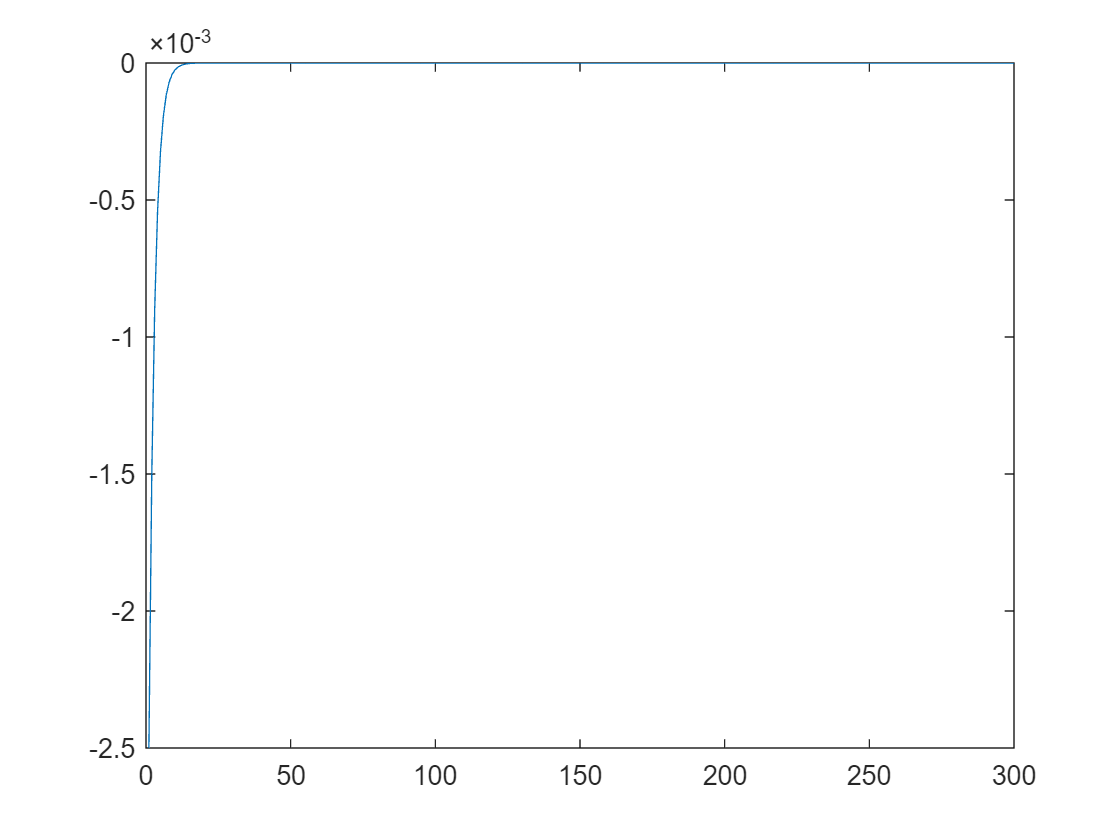

T = 300; % Transition periods
rho_r = 0.6; % persistence of monetary shock
sig_r = -0.01/4; % a negative interest rate shock of 25 basis points
m_shock_t = sig_r * rho_r.^(0:(T-1)); % the path of interest rate shock

figure;
plot(m_shock_t)

We then pass the monetary shock and the solved ss_rslt structure into "solve_trans_linear.m" to solve the linearized transition path.

options = struct;
options.T = T;
options.m_shock_t = m_shock_t;
tic;
trans_linear_rslt = solve_trans_linear(ss_rslt, options);
fprintf('Time used for solving the linearized transition path:\n');toc;

Time used for solving the linearized transition path:
Elapsed time is 64.028450 seconds.


trans_linear_rslt

trans_linear_rslt = struct with fields:
             var_agg_t: [1×1 struct]
       var_agg_shock_t: [1×1 struct]
      jacs_ind_wrt_agg: {5×5 cell}
    jac_eqs_of_var_agg: [2700×2700 double]
               irf_ssj: [2700×300 double]


We can plot the transition path (note that K is the next period capital).

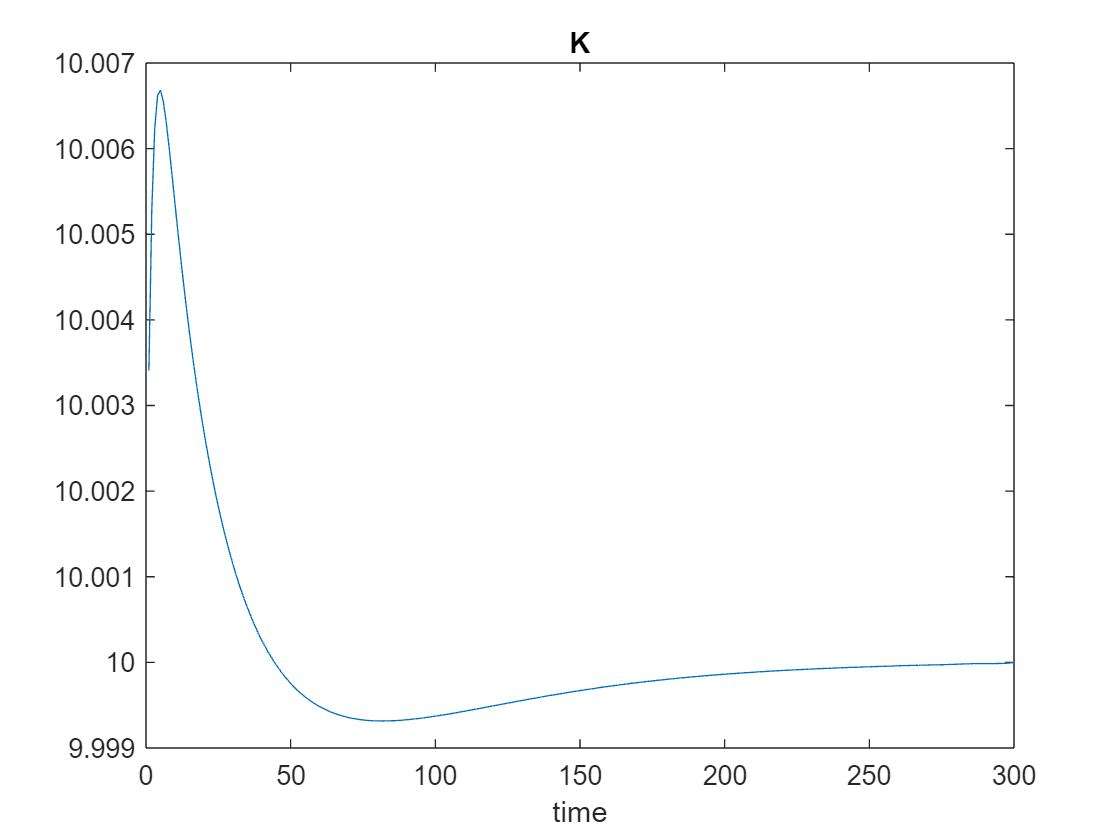

figure;
plot(trans_linear_rslt.var_agg_t.K)
title('K');
xlabel('time');

## Solve the nonlinear transition path

Now we pass the solved ss_rslt to solve_nonlinear_trans(init_ss, final_ss, options) to solve the nonlinear transition path.

Note that we pass ss_rslt structure as both init_ss and final_ss.

tic;
trans_nonlinear_rslt = solve_trans_nonlinear(ss_rslt, ss_rslt, options);

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   9.999633e-08   3.162220e-04

             1              1              2   2.404074e-10   1.550508e-05   1.405179e-03   1.000000e+00        Broyden


fprintf('Time used for solving the nonlinear transition path:\n');toc;

Time used for solving the nonlinear transition path:
Elapsed time is 113.535368 seconds.


trans_nonlinear_rslt

trans_nonlinear_rslt = struct with fields:
          var_agg_t: [1×1 struct]
    var_agg_shock_t: [1×1 struct]
                  T: 300
           vfi_rslt: [1×1 struct]
        shock_trans: [3×3 double]
           exitflag: 1
             HANS_x: [2700×1 double]
          eqs_resid: [2700×1 double]
          rslt_type: 'nonlinear_trans'
      solver_output: [1×1 struct]


We compare the solution of the nonlinear transition path and the linear transition path.

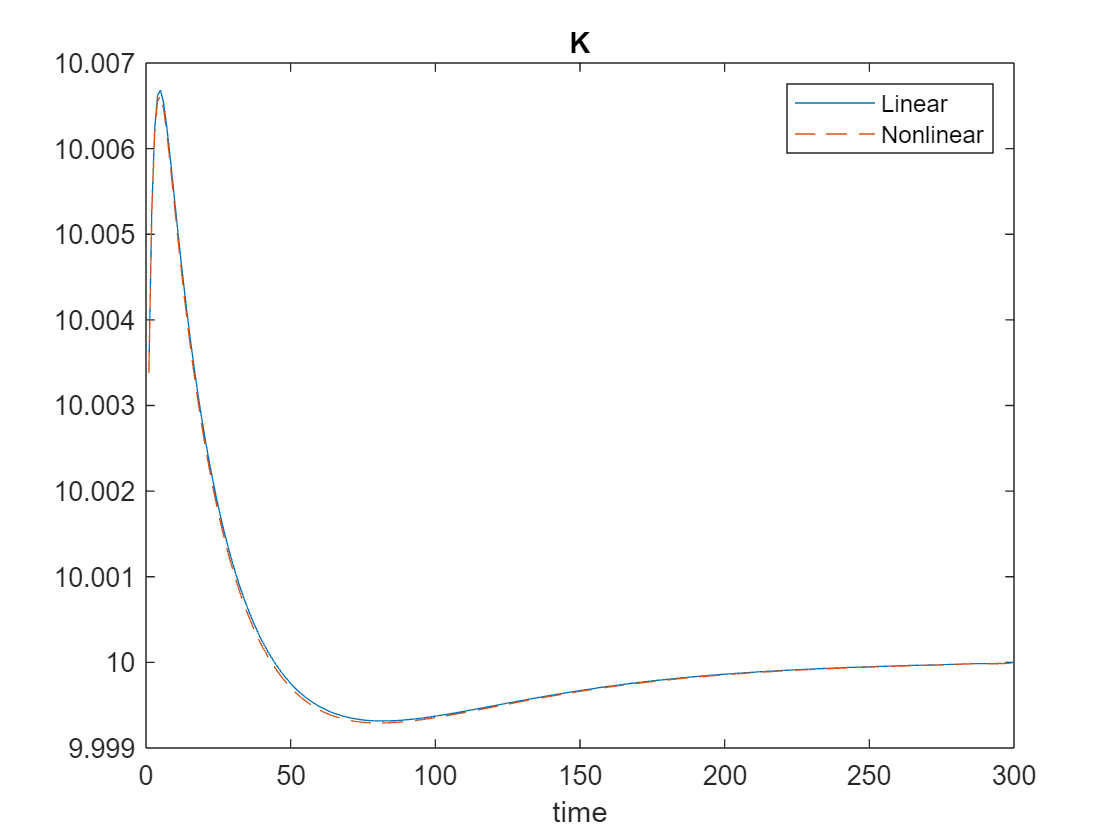

figure;
plot(trans_linear_rslt.var_agg_t.K);
hold on;
plot(trans_nonlinear_rslt.var_agg_t.K, '--');
xlabel('time');
title('K');
legend({'Linear','Nonlinear'});

We can also inspect other defined equilibrium varialbes along the transition path.

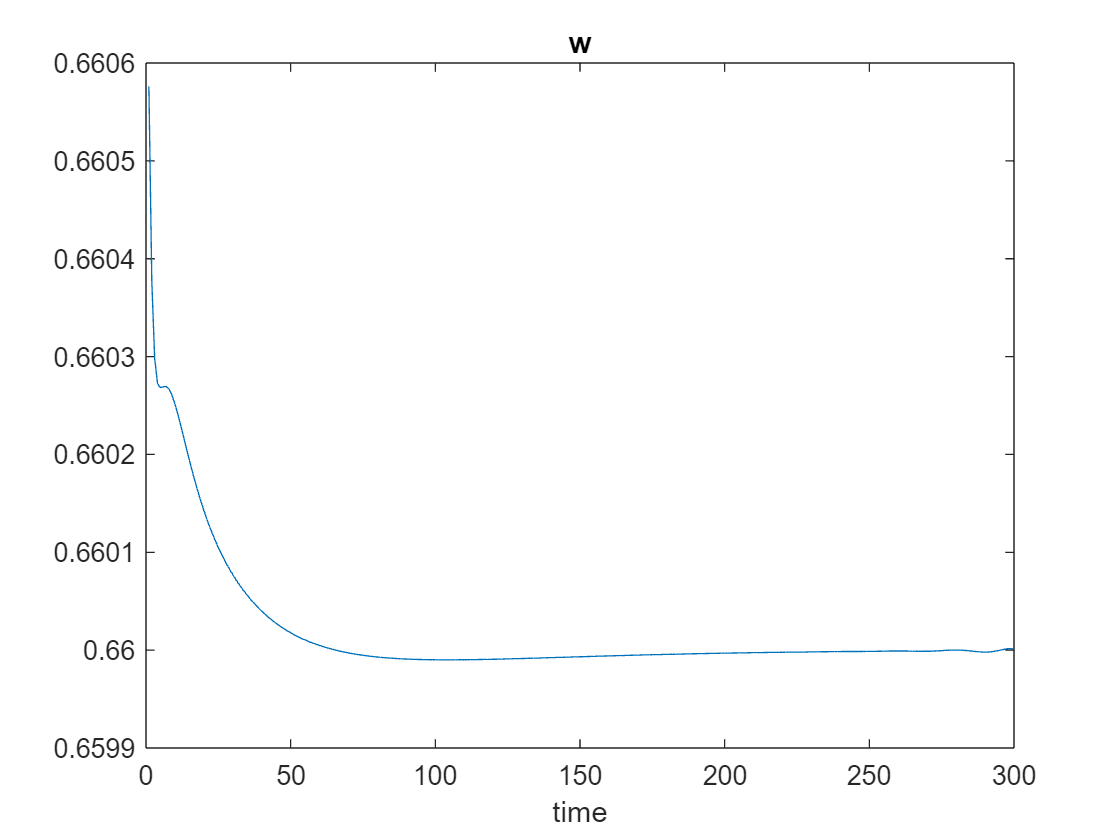

figure;
plot(trans_nonlinear_rslt.var_agg_t.w);
title('w');
xlabel('time');